## Планирование траектории Генетическим алгоритмом

## Выполнил:** студент группы R4236C Ларченков Артем **

clc;
clear;
close all;

## Инициализация

model = CreateModel();  % Создание структуры, представляющей модель

model.n = 3;  % Количество точек управления

CostFunction = @(x) MyCost(x, model);  % Функция стоимости

nVar = model.n;       % Количество переменных решения

VarSize = [1, nVar];   % Размер матрицы переменных решения

VarMin.x = model.xmin;           % Нижняя граница переменных
VarMax.x = model.xmax;           % Верхняя граница переменных
VarMin.y = model.ymin;           % Нижняя граница переменных
VarMax.y = model.ymax;           % Верхняя граница переменных

## Параметры генетического алгоритма

MaxIt = 500;          % Максимальное количество итераций

nPop = 100;           % Размер популяции (количество индивидуумов)

pc = 0.9;             % Вероятность кроссинговера
nc = 2 * round(pc * nPop / 2);  % Количество индивидуумов для кроссинговера (четное)

pm = 1;             % Вероятность мутации
nm = round(pm * nPop);  % Количество индивидуумов для мутации

%% Инициализация популяции

empty_particle.Position = struct('x', [], 'y', []);
empty_particle.Cost = [];
empty_particle.Sol = [];

pop = repmat(empty_particle, nPop, 1);

for i = 1:nPop
    pop(i).Position = CreateRandomSolution(model);
    [pop(i).Cost, pop(i).Sol] = CostFunction(pop(i).Position);
end

% Массив для хранения лучших значений стоимости на каждой итерации
BestCostGA = zeros(MaxIt, 1);

UpdateFrequency = 5;  % Частота обновления графика

## Основной цикл генетического алгоритма

Итерация 1: Лучшая стоимость = 424.4583, Нарушение = 0.0064114
Итерация 2: Лучшая стоимость = 96.1293 *
Итерация 3: Лучшая стоимость = 80.5244, Нарушение = 0.0019367
Итерация 4: Лучшая стоимость = 78.1389 *
Итерация 5: Лучшая стоимость = 170.4361 *
Итерация 6: Лучшая стоимость = 22.6315 *
Итерация 7: Лучшая стоимость = 16.3207 *
Итерация 8: Лучшая стоимость = 35.231 *
Итерация 9: Лучшая стоимость = 20.9621, Нарушение = 0.0012006
Итерация 10: Лучшая стоимость = 22.1829 *
Итерация 11: Лучшая стоимость = 140.3349 *
Итерация 12: Лучшая стоимость = 110.9645 *
Итерация 13: Лучшая стоимость = 26.9648 *
Итерация 14: Лучшая стоимость = 109.1042 *
Итерация 15: Лучшая стоимость = 80.8697 *
Итерация 16: Лучшая стоимость = 66.2935 *
Итерация 17: Лучшая стоимость = 18.8398 *
Итерация 18: Лучшая стоимость = 114.0575 *
Итерация 19: Лучшая стоимость = 89.1052 *
Итерация 20: Лучшая стоимость = 33.6185, Нарушение = 0.0022025
Итерация 21: Лучшая стоимость = 19.4237 *
Итерация 22: Лучшая стоимость = 17.865

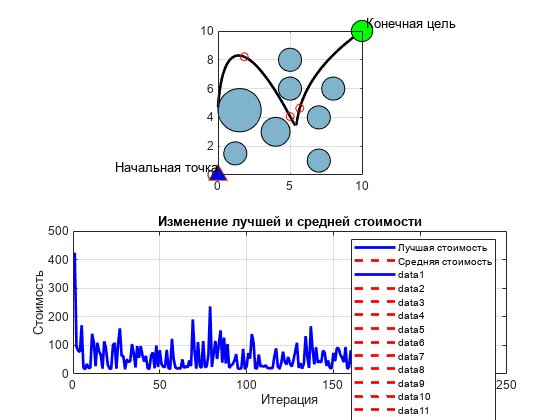


for it = 1:MaxIt
    
    % Оценка приспособленности
    costs = [pop.Cost];
    [costs, sortedIndices] = sort(costs);
    pop = pop(sortedIndices);
    
    % Сохранение лучшего решения
    BestSolGA = pop(1).Sol;
    BestCostGA(it) = pop(1).Cost;
    
    % Кроссинговер
    for k = 1:nc/2
        i1 = 2 * k - 1;
        i2 = 2 * k;
        [pop(i1).Position, pop(i2).Position] = Crossover(pop(i1).Position, pop(i2).Position);
        pop(i1).Position.x = max(VarMin.x, min(VarMax.x, pop(i1).Position.x));
        pop(i1).Position.y = max(VarMin.y, min(VarMax.y, pop(i1).Position.y));
        
        pop(i2).Position.x = max(VarMin.x, min(VarMax.x, pop(i2).Position.x));
        pop(i2).Position.y = max(VarMin.y, min(VarMax.y, pop(i2).Position.y));

    end
    
    % Мутация
    for k = 1:nm
        i = nPop - k + 1;
        pop(i).Position = Mutate(pop(i).Position, VarMin, VarMax);
        [pop(i).Cost, pop(i).Sol] = CostFunction(pop(i).Position);
    end
    
    % Обновление лучшей найденной стоимости
    BestCostGA(it) = pop(1).Cost;

    % Вывод информации о текущей итерации
    if  BestSolGA.IsFeasible
        Flag = ' *';
    else
        Flag = [', Нарушение = ' num2str( BestSolGA.Violation)];
    end
    disp(['Итерация ' num2str(it) ': Лучшая стоимость = ' num2str(BestCostGA(it)) Flag]);
    
    % Построение решения
    subplot(2,1,1)
    PlotSolution( BestSolGA, model);
    axis([model.xmin model.xmax model.ymin model.ymax]);  % Установка пределов осей
    pause(0.01);

        % Построение графика изменения лучшей и средней стоимости
    subplot(2,1,2)
    plot(1:it, BestCostGA(1:it), 'b', 'LineWidth', 2);
    hold on;
    plot(1:it, mean(costs), 'r--', 'LineWidth', 2);
    hold on
    title(['Изменение лучшей и средней стоимости']);
    xlabel('Итерация');
    ylabel('Стоимость');
    legend('Лучшая стоимость', 'Средняя стоимость');
    grid on;
end

## Результаты

figure;
plot(BestCostGA, 'LineWidth', 2, 'Color', 'b');
xlabel('Итерация');
ylabel('Лучшая стоимость');
title('График стоимости на каждой итерации генетического алгоритма');
grid on;

% Добавление линии, соединяющей значения стоимости
hold on;
plot(1:MaxIt, BestCostGA, '-o', 'LineWidth', 1, 'MarkerSize', 4, 'Color', 'r');

% Добавление меток крайних точек
text(1, BestCostGA(1), ['  (' num2str(1) ', ' num2str(BestCostGA(1)) ')']);
text(MaxIt, BestCostGA(MaxIt), ['  (' num2str(MaxIt) ', ' num2str(BestCostGA(MaxIt)) ')']);

legend('Генетический алгоритм', 'Location', 'Best');
hold off;

function [child1, child2] = Crossover(parent1, parent2)
    nVar = numel(parent1.x);
    
    % Случайный выбор точки кроссовера
    crossoverPoint = randi([1, nVar - 1]);
    
    % Выполнение кроссовера
    child1.x = [parent1.x(1:crossoverPoint), parent2.x(crossoverPoint + 1:end)];
    child1.y = [parent1.y(1:crossoverPoint), parent2.y(crossoverPoint + 1:end)];
    
    child2.x = [parent2.x(1:crossoverPoint), parent1.x(crossoverPoint + 1:end)];
    child2.y = [parent2.y(1:crossoverPoint), parent1.y(crossoverPoint + 1:end)];
end

function mutatedPosition = Mutate(position, VarMin, VarMax)
    nVar = numel(position.x);
    
    % Случайный выбор точки мутации
    mutationPoint = randi([1, nVar]);
    
    % Генерация случайного значения для мутации
    mutationValue = randn(size(position.x(mutationPoint)));
    
    % Применение мутации к выбранной точке
    mutatedPosition.x = position.x;
    mutatedPosition.x(mutationPoint) = position.x(mutationPoint) + mutationValue;
    
    mutationValue = randn(size(position.y(mutationPoint)));
    mutatedPosition.y = position.y;
    mutatedPosition.y(mutationPoint) = position.y(mutationPoint) + mutationValue;
    
    % Убедимся, что мутированная позиция находится в пределах ограничений
    mutatedPosition.x = max(VarMin.x, min(VarMax.x, mutatedPosition.x));
    mutatedPosition.y = max(VarMin.y, min(VarMax.y, mutatedPosition.y));
end